# A MATLAB script to evaluate longitudinal Automatic Tube Current Modulation (ATCM)

In this script we provide code to extract slice position and tube current from a CT scan and to generate synthetic radiographs from the CT image data. By plotting this information it is possible to gain insight into how longitudinal ATCM performed in the acquisition. We have annoted the script in detail to provide a clear explanation of the code. A stream-lined version of this live script (mlx-file) is provided as a minimally commented classic MATLAB script (m-file). You will find this alongside the live script in the GitHub repository.

## Section 1. Manage paths and files

We will clear all the variables in the workspace, before we start. This is good practice.

clear

Now let's begin. First we need to specify the folder in which the data is stored. We can do this using the function `uigetdir(). `

dataLocation = uigetdir();

This command opens a pop-up window that allows you to select the folder of interest by clicking. To use the example data provided, select the "Phantom" directory. In the code line, the folder location is returned as a *character array* and assigned to the `dataLocation` variable.

*    Note: MATLAB can represent text in two ways: as a *character array* or as a *string* (a more recent addtion to the language). Strings represent multiple characters as a single element. Thus *`a='text'`* defines a 1 x 4 character array while *`b="text"`* defines a 1 x 1 string.*

Now we need to get a list of all the DICOM files in the folder. We can do this using `dir()`. This function returns a *structure array* containing information about the files that match a search criterion. But first we have to define our search term. The function `strcat()` is used to concatenate (combine) the `dataLocation `and the DICOM file suffix, with a wildcard symbol (*) in between. The output is our search term as a character array. Note that the * symbol will match any combination of letters.

searchTerm = strcat(dataLocation,'/*.dcm');
files = dir(searchTerm);
numFiles = size(files,1);

At the end of this section we have a structure array called `files `containing information on the DICOM files of interest (one structure element for each file). We also used the function `size()` to obtain the number of files and assign this to a variable called `numFiles`.

    *Note: structures are data objects that can consist of an arbitrary number of fields that can represent various data types. The values for a field can be accessed or set using "dot" notation. For example, *`myStruct.myValue=1 `*sets the value for a field called *`myValue`* to 1 (and will create the structure *`myStruct `*if it doesn't already exist).*

## Section 2. Extract the slice locations and corresponding tube currents

We will proceed to extracting information on the slice location and tube current in each slice (i.e. each file).

It's handy to pre-allocate arrays of the correct length with zero initial values. We do this with the` zero()` function, which, in this case, creates arrays of dimension: `numFiles x 1`. 

sliceLocation = zeros(numFiles,1);
tubeCurrent = zeros(numFiles,1);

A for-loop will be used to iterate over the index `i, `accessing each file in turn. The `fullfile()` function is useful for handling the file path. It can be used to join a folder name and a filename to return the complete path to the ith file, which in this case is assigned to the `imagePath `variable. The` dicominfo()` function is then used to extract the metadata from the file as a structure and assign it to the variable `dicomMeta`.

Data in the `dicomMeta `structure is accessed by referencing the relevant field names. Two items of data are of interest: the x-ray tube current and the slice location. We know the DICOM tags of these: (20, 1041) and (18, 1151), respectively. However, we do not know what field names they are assigned in our MATLAB version. We check this in the code using the `dicomlookup()` function. The slice location and tube current values are then extracted from the metadata by referencing the fields of the structure and these are assigned to the ith element of the `sliceLocation` and `tubeCurrent `arrays.

fpop = msgbox("Processing data ... please wait!");

for i=1:numFiles
    
    imagePath = fullfile(files(i).folder,files(i).name);
   
    dicomMeta = dicominfo(imagePath);
    
    tagName = dicomlookup('20','1041'); % Slice Location
    sliceLocation(i) = dicomMeta.(tagName); % mm
    
    tagName = dicomlookup('18','1151'); % X-Ray Tube Current
    tubeCurrent(i) = dicomMeta.(tagName); % mAs
end

if ishandle(fpop)
    close(fpop)
end

Note that the for-loop is preceded by a line that creates a popup message (using `msgbox`). This is inessential stuff, but it lets you know that MATLAB is doing something and hasn't crashed when it's crunching through the CT slices. The if-statement below the for-loop uses the `ishandle()` function to check whether the pop-up still exists (if you haven't closed it) and closes it if necessary using the `close() `function. 

We have extracted the desired data. Unfortunately, there is no guarantee that the file order listed in files is in sequential order. For that reason, the `sort()` function is used to extract the indices of the slices in order of ascending slice position. This array of indices is then used to reorder the `tubeCurrent `and `sliceLocation` arrays. 

 *   Note: below, the "~" symbol simply indicates that another variable is output by the* `sort()`* function but that we are not interested in assigning it a variable name.*

[~,I] = sort(sliceLocation);

tubeCurrent = tubeCurrent(I);
sliceLocation = sliceLocation(I);

We have now successfully extracted the information on longitudinal tube current modulation by slice. 

## Section 3. Generate a synthetic radiograph

To visually assess the longitudinal tube current modulation against the size of the phantom, we will generate synthetic radiographs. Such a radiograph is found by summing or averaging the CT number along an axis. It therefore resembles a scan projection radiograph (SPR)---AKA localizer radiograph or scout view---except that it represents a non-divergent (parallel-beam) geometry.

To generate a synthetic radiograph we need to access the image data for the CT scan. It is possible to iterate through the slices in turn and extract the pixel data using `dicomread()`, but there is a simpler way. The function `dicomreadVolume()` can be used to extract a complete volume from a series of CT slices in one shot. We use this below, passing it the location of the DICOM files.

[rawDicomVolume, ~, ~] = dicomreadVolume(dataLocation);

The `rawDICOMVolume `variable returned has dimensions: 512 x 512 x 1 x 169. The first two dimensions denote a 512x512 pixel matrix (x-y plane) and the last the number of slices (169). The third dimension denotes the dimension of digital number corresponding to a pixel. Since CT number is a scalar value (grayscale), this is just 1, which is known as a singlet dimension. To simplify, the `squeeze()` function is used below to reduce the image volume to a 512 x 512 x 169 array.

Digital number is not CT-number. Encoded in the metadata is the linear transform necessary to transform it to Hounsfield Units (the `RescaleSlope` and `RescaleIntercept `fields). Below, we also add an extra 1000 to obtain "CT number" on a scale where air takes the value 0 and water 1000. This definition is sometimes called *reduced CT number* or *scaled CT number* in radiotherapy and is equal to the spectral-averaged linear attenuation coefficient in a voxel, relative to water, multiplied by 1000.

rawDicomVolume = squeeze(rawDicomVolume);
dicomVolume = rawDicomVolume*dicomMeta.RescaleSlope + dicomMeta.RescaleIntercept ...
    + 1000; 

Outside the reconstruction field-of-view, the CT number is often set to an unphysical value (the value is vendor-dependent). The line below catches these nonsensical values and sets them to zero (i.e. to air).

dicomVolume(dicomVolume<-24) = 0;

We can now generate the AP and LAT synthetic radiographs by averaging over the first and second dimension of the image volume, respectively. The `mean()` function performs the averaging and returns a 512 x 1 x 169 array which is reduced to 512 x 169 by use of the `squeeze()` function again.

syntheticRadiographAP = squeeze(mean(dicomVolume,1));
syntheticRadiographLAT = squeeze(mean(dicomVolume,2));

At this stage we have tube current data and our synthetic radiographs. Now, it only remains to display the data.

## Section 4. Plot results

More than half of the lines of code of this script will be devoted to plotting the results. Although MATLAB is handy for quick plotting, to get things looking exactly like you want can take some extra work. We have tried to annotate fully for the sake of clarity.

First of all we, we create a figure. The `figure()` commands create it and returns a figure handle `fh`. This is convenient as we can the access properties of the figure using the handle. We do so in the next two lines, where we set the window state to maximized and make the figure visible as a plot window (rather than just inline in this live script). This figure will now take up the whole screen: something that's useful in our example, to ensure the figure is displayed corretly.

fh = figure();
fh.WindowState = 'maximized';
fh.Visible = 'on';

The above three lines were optional in the sense that without them, a figure would still be implicitly generated when we plot something, but it would be in a smaller 'normal' window state. Now we get to plotting the data. We will do this by splitting the figure into four subplots (2 x 2). 

### Subplot 1

The next line creates a subplot in the figure using the `subplot()` command. The first two indices of the command define the number of rows and colums in the subplot. The third index refers to the subplot position in the order of top-left, top-right, bottom-left, bottom-right. Here we use subplot position 1 (top-left).

subplot(2,2,1)

In this plot we will display the synthetic AP radiograph. As it's a radiograph, we want to ensure that the intensity value is represented by a grayscale value. We do this by setting the colormap to gray.

colormap gray;

We will display the image with the x-axis being distance and the y-axis being pixel number. The first two lines below extract the minimum and maximum slice locations and assign to the variables `sliceLocationMin` and `sliceLocationMax`, respectively. The third line finds the number of pixels, by looking at the size of the first dimension of synthetic radiograph image, and assigns the value to the variable `numPixels`.  The fourth and fifth lines use the `linspace()` function to generate arrays carrying the appropriate x- and y- axis values, respectively.

   * Note: *`linspace(A, B, N)`* splits the range from *`A `*to *`B`* into *`N`* equally spaced values and returns them as an array.*

sliceLocationMin = min(sliceLocation); 
sliceLocationMax = max(sliceLocation); 
numPixels = size(syntheticRadiographAP,1);
imgXValues = linspace(sliceLocationMin, sliceLocationMax, numFiles);
imgYValues = linspace(0, numPixels-1, numPixels);

Now we will display the image. For this we use the `imagesc()` function which displays a 2D image with the intensity values automatically scaled to match the display range. The first two arguments are the x- and y -axis values corresponding to the pixel matrix, which is passed as the third argument. The next line uses the `axis xy` command to set the origin to be in the bottom left of the subplot, as we want the zero pixel to be on the bottom left (the default is top-left for images in MATLAB). Note that we also use the `flip()` function to flip the columns of the image, as otherwise the image would look upside down.

The `title()` function adds a title to the figure and `xlabel()` and `ylabel()` add labels to the x- and y-axis, respectively. 

imagesc(imgXValues,imgYValues,flip(syntheticRadiographAP))
axis xy

title('Synthetic radiograph of phantom (anterior-posterior)')
xlabel('Distance [mm]')
ylabel('Pixel [#]')

### Subplot 2

Now we repeat (some of) these steps to display the LAT synthetic radiograph in a subplot positioned at the top-right of the figure (subplot position 2).

subplot(2,2,2)

colormap gray;

imagesc(imgXValues,imgYValues,flip(syntheticRadiographLAT))
axis xy

title('Synthetic radiograph of phantom (lateral)')
xlabel('Distance [mm]')
ylabel('Pixel [#]')

### Subplot 3

Now we create a subplot in the bottom left (subplot position 3) and display a plot of `tubeCurrent` against `sliceLocation` using the `plot() `function. The `xlim()` and `ylim()` functions set the range for the x- and y-axis, respectively. A title and the axes labels are also added as previously.

subplot(2,2,3)

plot(sliceLocation,tubeCurrent)
ylim([0 1.05*max(tubeCurrent)])
xlim([min(sliceLocation) max(sliceLocation)])

title('Tube current modulation')
xlabel('z-axis position [mm]')
ylabel('Tube current [mA]')

### Subplot 4

The first three subplots have displayed all the pertinent information. In the fourth and last plot we will get fancy: we overlay a synthetic radiograph with the tube current profile. This is a nice way to display the information.

subplot(2,2,4)

colormap gray;

We have created a new subplot (at bottom-right or position 4) with a grayscale colormap. Now we need to create a new array with the y-values to pass to the `imagesc() `function. This is necessary, as we need the y-axis values of the radiograph image to match the range of the tube current values.

tubeCurrentMin = 0;
tubeCurrentMax = max(max(tubeCurrent))*1.05;
imgYValues = linspace(tubeCurrentMin, tubeCurrentMax, numFiles);

Now we plot the LAT synthetic radiograph.

imagesc(imgXValues, imgYValues,flip(syntheticRadiographLAT))
axis xy
hold on

We added the` hold on` here, so this plot doesn't disappear when we add another. Now we add the tube current profile, as for subplot 3, but assigning dots to data points this time rather than using the default of a joined-up curve.

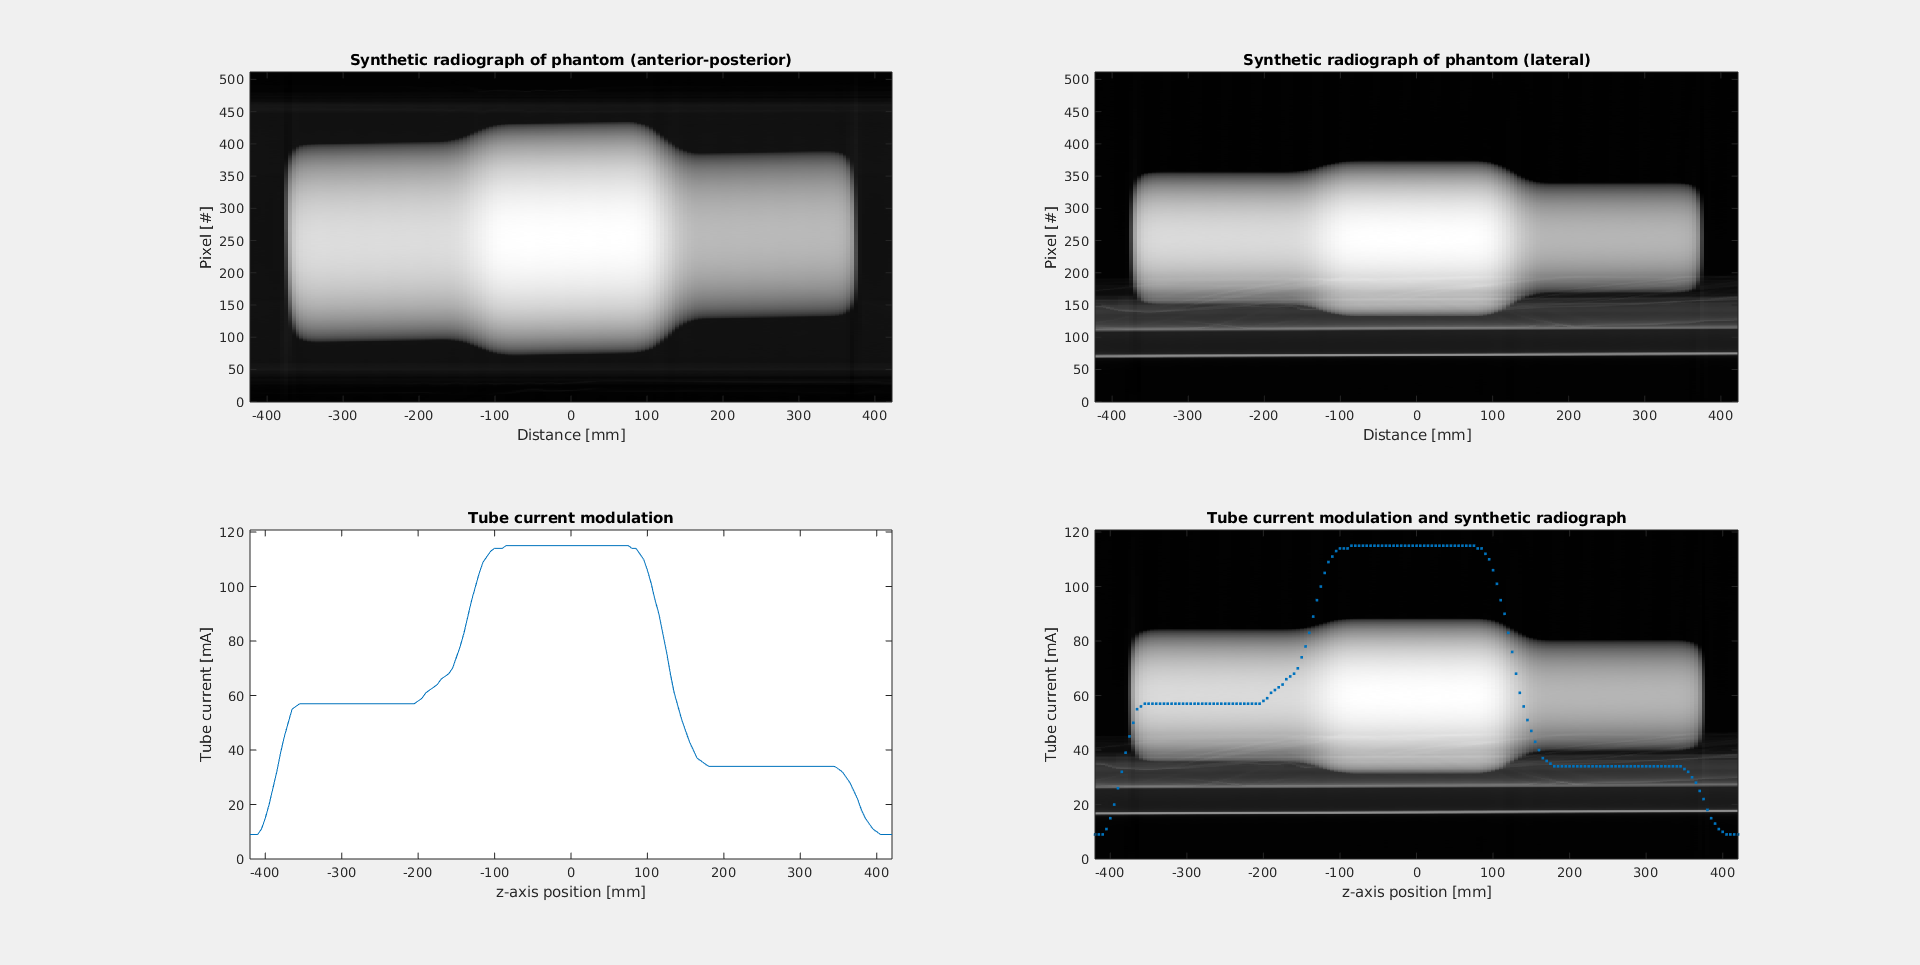

plot(sliceLocation, tubeCurrent, '.');
xlabel('z-axis position [mm]')
ylabel('Tube current [mA]')

title('Tube current modulation and synthetic radiograph')
xlim([min(sliceLocation) max(sliceLocation)])
ylim([0 1.05*max(tubeCurrent)])

Now we have finished. We hope this detailed explanation has been useful to you!

*Gavin Poludniowski (gavin.poludniowski@regionstockholm.se)*